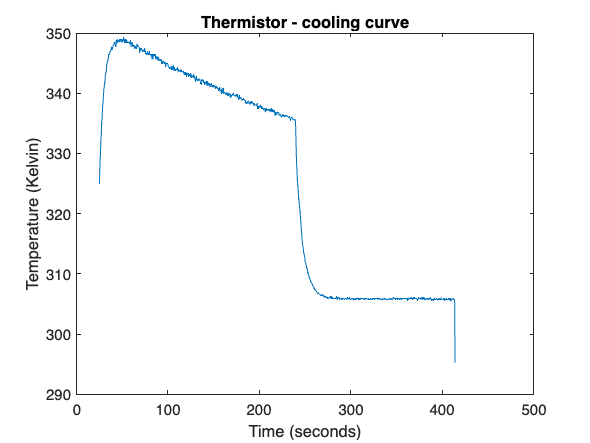

clear; % clears memory - useful if you run many scripts in the same session
clf;

%take in data from csv file
tname='Lab2thermistor.csv'; % <-input your data file's name! test2.csv was exported from O-scope software with a line of headers
datatable  = readtable(tname);%makes data table with headers

%interpret data as times and voltages
time1  = datatable.t1; % stores the t1 column of data in a variable called time1 
time1 = time1 + 400;
V1    = datatable.ch1; % stores the ch1 column of data in a variable called V1   
time2    = datatable.t2; %stores the t2 column of data in a variable called time2 
V2 = datatable.ch2; %stores the ch2 column of data in a variable called V2   

R = (5000 - (1000.*V1))./V1;
a = log(R/1000);
b = a + (3528/298);
T = 3528./b;

%plot (you can change this section to suit your plotting needs!)
plot(time1(1:779),T(1:779)) %plots first channel
xlabel('Time (seconds)'); % add x axis label 
ylabel('Temperature (Kelvin)'); % add y axis label 
title('Thermistor - cooling curve');